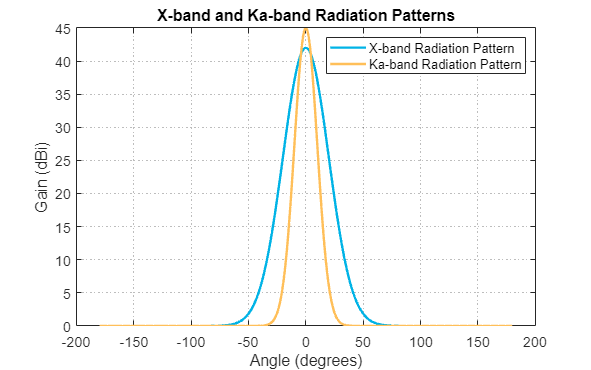

%% MAPLE Communication System Analysis - Mars Orbiter
% Using specifications from MAPLE component table

clear; clc; close all;

%% Constants
c = 3e8;                % Speed of light [m/s]
k = 1.38e-23;           % Boltzmann constant [J/K]

%% Mission Parameters
d_mars_earth = 2.25e11; % Mars-Earth average distance [m]
d_surface_orbiter = 1000e3; % Surface-to-orbiter distance [m]

%% System Parameters (From MAPLE Component Specifications Table)
% X-Band
f_x = 8.41e9;           % X-band frequency [Hz] - Table value
P_tx_x_W = 100;         % X-band transmitter power [W] - Table value
G_tx_x = 42;            % X-band transmit antenna gain [dBi] - Table value
G_rx_x = 68;            % X-band receive antenna gain (DSN) [dBi]

% Ka-Band
f_ka = 32e9;            % Ka-band frequency [Hz] - Table value
P_tx_ka_W = 80;         % Ka-band transmitter power [W] - Table value
G_tx_ka = 45;           % Ka-band transmit antenna gain [dBi] - Table value
G_rx_ka = 70;           % Ka-band receive antenna gain (DSN) [dBi]

% UHF Relay
f_uhf = 401.5e6;        % UHF relay frequency [Hz] - Using center of 390-450 MHz range
P_tx_surface_W = 15;    % Surface transmitter power [W] - Table value
G_tx_surface = 2;       % Surface UHF antenna gain [dBi] - Table value
G_rx_orbiter = 8;       % Orbiter UHF antenna gain [dBi] - Table value
receiver_sensitivity_uhf = -110; % UHF receiver sensitivity [dBm] - Table value

% RAD5545 SBC Parameters
rad5545_power = 35;     % Power consumption [W] - Table value
rad5545_throughput = 5.6; % Processing capability [GOPS] - Table value
rad5545_TID = 100;      % Total Ionizing Dose [krad(Si)] - Table value
rad5545_SEU = 1e-3;     % SEU rate [upsets/card-day] - Table value

%% Loss Factors [dB]
L_misc_ds = 3;          % Deep space miscellaneous losses
L_misc_surf = 2.5;      % Surface-to-orbiter miscellaneous losses

%% Antenna Return Loss (VSWR) Parameters
vswr_x = 1.3;           % VSWR for X-band
vswr_ka = 1.5;          % VSWR for Ka-band

%% FSPL Calculation
fspl_dB = @(d,f) 20*log10((4*pi*d*f)/c);

% Calculate FSPL at nominal distances
L_fs_x_dB = fspl_dB(d_mars_earth, f_x);
L_fs_ka_dB = fspl_dB(d_mars_earth, f_ka);
L_fs_uhf_dB = fspl_dB(d_surface_orbiter, f_uhf);

%% Received Power Calculation
rx_power_dBm = @(Ptx,Gtx,Lfs,Lmisc,Grx) ...
    (10*log10(Ptx*1e3) + Gtx - Lfs - Lmisc + Grx);

% Calculate Received Powers
P_rx_x_dBm = rx_power_dBm(P_tx_x_W, G_tx_x, L_fs_x_dB, L_misc_ds, G_rx_x);
P_rx_ka_dBm = rx_power_dBm(P_tx_ka_W, G_tx_ka, L_fs_ka_dB, L_misc_ds, G_rx_ka);
P_rx_uhf_dBm = rx_power_dBm(P_tx_surface_W, G_tx_surface, L_fs_uhf_dB, L_misc_surf, G_rx_orbiter);

%% Receiver Sensitivities
receiver_sensitivity_x = -130; % X-band DSN receiver sensitivity [dBm]
receiver_sensitivity_ka = -130; % Ka-band DSN receiver sensitivity [dBm]

%% Link Margin Calculation
link_margin_x = P_rx_x_dBm - receiver_sensitivity_x;
link_margin_ka = P_rx_ka_dBm - receiver_sensitivity_ka;
link_margin_uhf = P_rx_uhf_dBm - receiver_sensitivity_uhf;

%% Noise Power Calculation
noise_power_dBm = @(Tsys,B) 10*log10(k*Tsys*B*1e3);

% Noise Parameters
T_sys_ds = 500; B_ds = 1e6;
T_sys_uhf = 300; B_uhf = 4e6;

% Calculate Noise Powers
P_noise_ds_dBm = noise_power_dBm(T_sys_ds,B_ds);
P_noise_uhf_dBm = noise_power_dBm(T_sys_uhf,B_uhf);

%% SNR Calculation
SNR_x_dB = P_rx_x_dBm - P_noise_ds_dBm;
SNR_ka_dB = P_rx_ka_dBm - P_noise_ds_dBm;
SNR_uhf_dB = P_rx_uhf_dBm - P_noise_uhf_dBm;

%% BER Calculation (QPSK for X/UHF, 16-QAM for Ka)
BER_x = 0.5*erfc(sqrt(10.^(SNR_x_dB/10)));          % QPSK
BER_ka = 0.5*erfc(sqrt(10.^(SNR_ka_dB/10)/log2(16))); % 16-QAM
BER_uhf = 0.5*erfc(sqrt(10.^(SNR_uhf_dB/10)));      % QPSK

%% Channel Capacity Calculation (Shannon)
capacity_bps = @(B,SNRdB) B.*log2(1+10.^(SNRdB/10));

C_x_bps = capacity_bps(B_ds,SNR_x_dB);
C_ka_bps = capacity_bps(B_ds,SNR_ka_dB);
C_UHF_bps = capacity_bps(B_uhf,SNR_uhf_dB);

%% Effective Throughput (Assuming overhead)
overhead_ds = 0.20; overhead_UHF = 0.15;

throughput_x_bps = C_x_bps*(1-overhead_ds);
throughput_ka_bps = C_ka_bps*(1-overhead_ds);
throughput_UHF_bps = C_UHF_bps*(1-overhead_UHF);

%% Daily Data Return Calculation
contact_time_x = 8 * 3600;    % 8 hours per day X/Ka-band
contact_time_uhf = 24 * 3600; % 24 hours per day UHF

data_x_gb = (throughput_x_bps * contact_time_x) / 8e9;
data_ka_gb = (throughput_ka_bps * contact_time_x) / 8e9;
data_uhf_gb = (throughput_UHF_bps * contact_time_uhf) / 8e9;

%% Component-by-Component Power Calculations
% Define components and their peak/average power usage (in Watts)
components = {
    'X-band TWTA', 250, 62.5; % Peak, Average (25% duty cycle)
    'Ka-band TWTA', 200, 50; % Peak, Average (25% duty cycle)
    'UHF Transceiver', 28, 11.2; % Peak, Average (40% duty cycle)
    'Antenna Pointing', 25, 2.5; % Peak, Average (10% duty cycle)
    'RAD5545 SBC', 35, 35; % Peak and Average (continuous operation) - Table value
    'Solid State Recorder', 15, 15; % Peak and Average (continuous operation)
};

% Extract power data for calculations
component_names = components(:,1);
peak_powers = cell2mat(components(:,2));
average_powers = cell2mat(components(:,3));

% Total power calculations
total_peak_power = sum(peak_powers);
total_average_power = sum(average_powers);

%% Plot 1: Antenna Radiation Patterns
angles = linspace(-180, 180, 360);  % degrees

% Main lobe widths (degrees)
main_lobe_width_x = 20;
main_lobe_width_ka = 10;

% Simulate radiation patterns using Gaussian approximation
pattern_x = G_tx_x * exp(-0.5 * (angles / main_lobe_width_x).^2);
pattern_ka = G_tx_ka * exp(-0.5 * (angles / main_lobe_width_ka).^2);

% Zero out negative values (not physically possible in dBi)
pattern_x(pattern_x < 0) = 0;
pattern_ka(pattern_ka < 0) = 0;

figure('Name', 'X-band and Ka-band Radiation Patterns', 'Position', [100, 100, 800, 500]);
plot(angles, pattern_x, 'Color', [0, 0.7, 0.9], 'LineWidth', 2);
hold on;
plot(angles, pattern_ka, 'Color', [1, 0.75, 0.35], 'LineWidth', 2);
grid on;
xlabel('Angle (degrees)');
ylabel('Gain (dBi)');
title('X-band and Ka-band Radiation Patterns');
legend('X-band Radiation Pattern', 'Ka-band Radiation Pattern');
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.3;
ax.FontSize = 12;

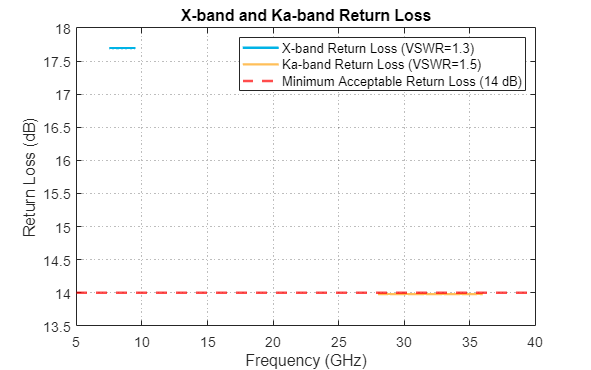


%% Plot 2: Return Loss 
% Calculate Reflection Coefficient from VSWR
Gamma_x = (vswr_x - 1) / (vswr_x + 1);
Gamma_ka = (vswr_ka - 1) / (vswr_ka + 1);

% Return Loss (dB)
return_loss_x = -20 * log10(Gamma_x);
return_loss_ka = -20 * log10(Gamma_ka);

% Create frequency ranges for plotting
freq_x = linspace(7.5, 9.5, 100);
freq_ka = linspace(28, 36, 100);

figure('Name', 'Return Loss', 'Position', [100, 100, 800, 500]);
plot(freq_x, return_loss_x * ones(size(freq_x)), 'Color', [0, 0.7, 0.9], 'LineWidth', 2);
hold on
plot(freq_ka, return_loss_ka * ones(size(freq_ka)), 'Color', [1, 0.75, 0.35], 'LineWidth', 2);
yline(14, 'r--', 'LineWidth', 2);
grid on;
xlabel('Frequency (GHz)');
ylabel('Return Loss (dB)');
title('X-band and Ka-band Return Loss');
legend('X-band Return Loss (VSWR=1.3)', 'Ka-band Return Loss (VSWR=1.5)', 'Minimum Acceptable Return Loss (14 dB)');
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.3;
ax.FontSize = 12;

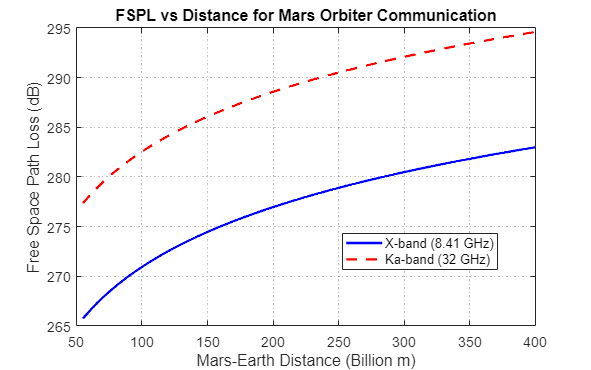


%% FSPL vs Distance
d_min = 5.5e10; d_max = 4.0e11;
distance = linspace(d_min, d_max, 1000);
FSPL_X_band = fspl_dB(distance, f_x);
FSPL_Ka_band = fspl_dB(distance, f_ka);

figure('Name', 'FSPL vs Distance', 'Position', [100, 100, 800, 500]);
plot(distance/1e9, FSPL_X_band, 'b-', 'LineWidth', 2); hold on;
plot(distance/1e9, FSPL_Ka_band, 'r--', 'LineWidth', 2); grid on;
xlabel('Mars-Earth Distance (Billion m)');
ylabel('Free Space Path Loss (dB)');
title('FSPL vs Distance for Mars Orbiter Communication');
legend('X-band (8.41 GHz)', 'Ka-band (32 GHz)', 'Location', 'best');
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.3;
ax.FontSize = 12;


%% Display Component-by-Component Power Data
fprintf('\n--- Component-by-Component Power Usage ---\n');


--- Component-by-Component Power Usage ---


fprintf('%-25s %-15s %-15s\n', 'Component', 'Peak Power (W)', 'Average Power (W)');

Component                 Peak Power (W)  Average Power (W)


for i = 1:length(component_names)
    fprintf('%-25s %-15.2f %-15.2f\n', component_names{i}, peak_powers(i), average_powers(i));
end

X-band TWTA               250.00          62.50          
Ka-band TWTA              200.00          50.00          
UHF Transceiver           28.00           11.20          
Antenna Pointing          25.00           2.50           
RAD5545 SBC               35.00           35.00          
Solid State Recorder      15.00           15.00          


fprintf('------------------------------------------\n');

------------------------------------------


fprintf('Total Peak Power: %.2f W\n', total_peak_power);

Total Peak Power: 553.00 W


fprintf('Total Average Power: %.2f W\n\n', total_average_power);

Total Average Power: 176.20 W




%% Display Comprehensive Link Budget Results
fprintf('\n--- MAPLE Communication System Link Budget ---\n');


--- MAPLE Communication System Link Budget ---


fprintf('%-12s %-13s %-8s %-13s %-10s %-11s %-12s\n', 'Link', 'Rx Power (dBm)', 'Margin (dB)', 'SNR (dB)', 'BER', 'Data Rate', 'GB/day');

Link         Rx Power (dBm) Margin (dB) SNR (dB)      BER        Data Rate   GB/day      


fprintf('%-12s %-13.2f %-8.2f %-13.2f %-10.1e %-11.2f %-12.2f\n', ...
    'X-band', P_rx_x_dBm, link_margin_x, SNR_x_dB, BER_x, throughput_x_bps/1e6, data_x_gb);

X-band       -120.98       9.02     -9.37         3.2e-01    0.13        0.45        


fprintf('%-12s %-13.2f %-8.2f %-13.2f %-10.1e %-11.2f %-12.2f\n', ...
    'Ka-band', P_rx_ka_dBm, link_margin_ka, SNR_ka_dB, BER_ka, throughput_ka_bps/1e6, data_ka_gb);

Ka-band      -128.56       1.44     -16.95        4.6e-01    0.02        0.08        


fprintf('%-12s %-13.2f %-8.2f %-13.2f %-10.1e %-11.2f %-12.2f\n', ...
    'UHF Relay', P_rx_uhf_dBm, link_margin_uhf, SNR_uhf_dB, BER_uhf, throughput_UHF_bps/1e6, data_uhf_gb);

UHF Relay    -95.25        14.75    12.55         9.8e-10    14.45       156.01      



%% RAD5545 SBC Capability Summary
fprintf('\n--- RAD5545 SBC Capabilities ---\n');


--- RAD5545 SBC Capabilities ---


fprintf('Processing Capability: %.1f GOPS\n', rad5545_throughput);

Processing Capability: 5.6 GOPS


fprintf('Power Consumption: %.1f W\n', rad5545_power);

Power Consumption: 35.0 W


fprintf('Total Ionizing Dose: %.0f krad(Si)\n', rad5545_TID);

Total Ionizing Dose: 100 krad(Si)


fprintf('SEU Rate: %.1e upsets/card-day\n', rad5545_SEU);

SEU Rate: 1.0e-03 upsets/card-day


fprintf('SpaceWire Interfaces: 12 links at 320 Mbps each\n');

SpaceWire Interfaces: 12 links at 320 Mbps each


fprintf('RapidIO Ports: 4 ports at 3.125 Gbaud/lane\n');

RapidIO Ports: 4 ports at 3.125 Gbaud/lane


%{
%% System Closure Analysis
fprintf('\n--- System Closure Analysis ---\n');
fprintf('X-band Link: %s (%.2f dB margin)\n', (link_margin_x > 0 && BER_x < 1e-5)  "CLOSED" : "OPEN", link_margin_x);
fprintf('Ka-band Link: %s (%.2f dB margin)\n', (link_margin_ka > 0 && BER_ka < 1e-5)  "CLOSED" : "OPEN", link_margin_ka);
fprintf('UHF Relay Link: %s (%.2f dB margin)\n', (link_margin_uhf > 0 && BER_uhf < 1e-5)  "CLOSED" : "OPEN", link_margin_uhf);
fprintf('Power Budget: %s (%.2f W margin with 230W solar array)\n', total_average_power < 230  "CLOSED" : "OPEN", 230-total_average_power);
%}